# Optimal Missile Guidance

In this exercise you will implement a simple model of missile dynamics and guidance, use an ODE solver to estimate the missile trajectory and then implement an optimization solver to find the optimal guiance parameters that balance time-to-target and energy useage (control effort).  

- Create a model of the open-loop missile dynamics and implement a numerical solution to the model to predict the trajectory.

- Incorporate Augmented Proportional Navigtion (APN), a common guidance technique to guide the simulated missile to a fixed target.

- Explore the sensitivity of the performance to the APN parameters.

- Formulate a cost function to balance trajectory time and effort.

- Use optimization to find the "best" guidance parameters to minimize time and effort.

The steps below are meant to be incremental, putting the pieces together one at a time to formulate the optimization problem.  Because of this repetition, the live script is rather lengthy.   You will need to read through the existing code to understand the intent.  Here there is this comment:

%% Your Code Here.

you will need to add code following the instructions from the text blocks.

## Missile Model

Create a model of the open-loop missile dynamics and implement a numerical solution to the model to predict the trajectory.

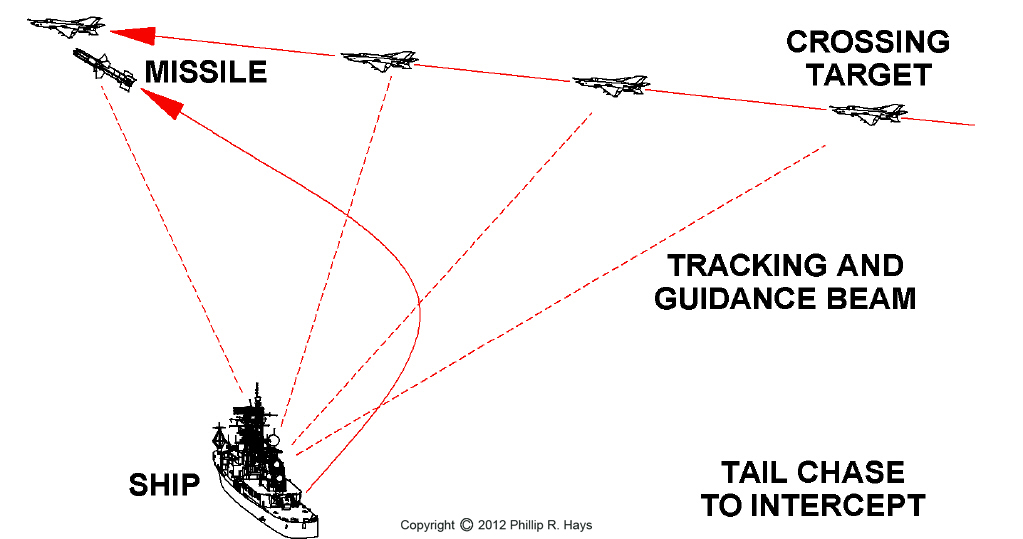

Consider a simple kinematic model of a missile in the horizontal plane.

The state of the system is defined as


$$\mathbf{x}(t)=\left\{ \matrix{ x(t) \cr y(t)\cr \dot{x}(t) = v_x(t) \cr \dot{y}(t) = v_y(t) }\right\}
$$


where 

- $x(t)$ is the position east

- $y(t)$ is the position north

- $v_x(t)$ is thevelocity component in the east direction

- $v_y(t)$ is the velocity component in the north direction.

This rate function describes a simple kinematic model in 2D with zero acceleration.

function dxxdt = missile(t, xx)
    % First, unpack the state vector 
    x = xx(1);   % m
    y = xx(2);   % m
    vx = xx(3);  % m/s
    vy = xx(4);  % m/s

    % Next, write your equations of motion
    dxdt = vx;      % m/s
    dydt = vy;      % m/s
    dvxdt = 0;      % m/s^2
    dvydt = 0;  % m/s^2
    
    % Finally, reassemble the output vector dX/dt
    dxxdt= [dxdt;dydt;dvxdt;dvydt];
end

We'll consider a reasonable initial velocity based on the [RIM-174 Standard ERAM](https://en.wikipedia.org/wiki/RIM-174_Standard_ERAM)

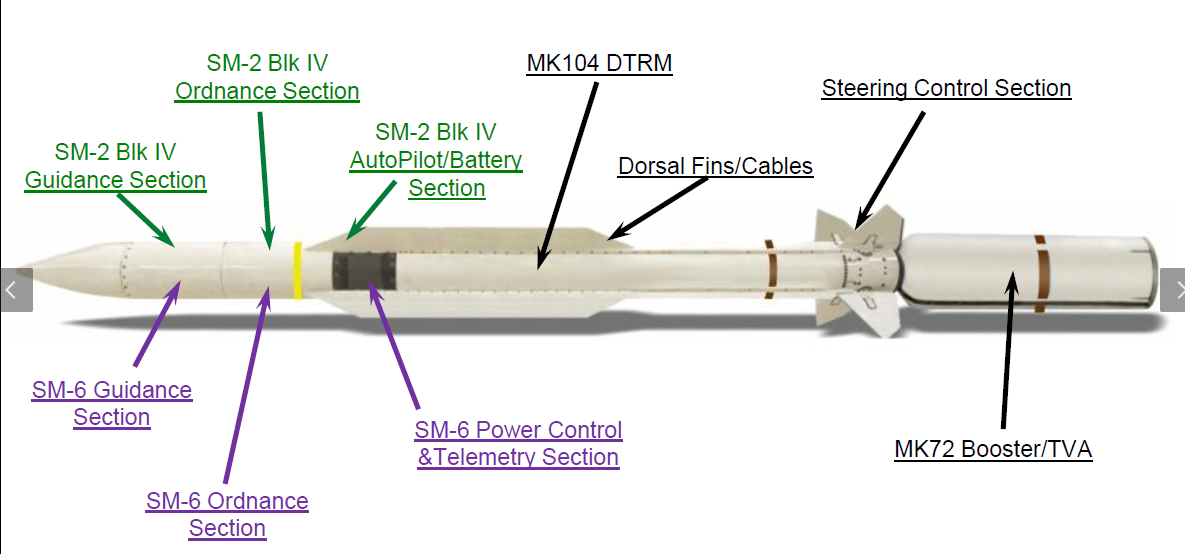

For this exercise we'll consider this constant set of initial conditions, including a constant firing angle of north-east (45 degrees).

% Initial conditions
% RIM-174 ERAM Standard SM-6
v0 = 1200; % m/s
theta = pi/4;  % rad
x0 = 0;
y0 = 0;
vx0 = v0*cos(theta);
vy0 = v0*sin(theta);
xx0 = [x0; y0; vx0; vy0];


Use `ode45` to simulate the missile dynamics for 100 seconds with the initial conditions above.

% Time span
tspan = [0, 100];

% Solver
%% Your Code Here.

From the dynamics, we would expect that the missile would travel a straight trajectory to the northeast.    Plot the trajectory (x vs y states) of the missile to verify that the results match our prediction.   Plot the distances in units of km to make it a bit easier to view.

%% Your Code Here.

Furthermore, based on the velocity and the time span we could estimate how far it would travel. Are the results (the plot) consistent with your estimate?

## Implement Augmented Proportional Navigation (APN) and Fixed Target

Incorporate Augmented Proportional Navigtion (APN), a common guidance technique to guide the simulated missile to a fixed target.

Now that we have the missile dynamics working we can add the guidance law and a fixed target location.   The [APN guidlance law](https://en.wikipedia.org/wiki/Proportional_navigation) is expressed as


$$a_n = N \dot{\lambda} V + B$$


where

- $a_n$ is the normal acceleration

- $N$is the proportioal gain design parameter

- $\dot{\lambda}$ is the rate of change of the line of sight from the missile to the target

- $V $is the closing velocity.

To implement this guidance law we need to be able to formulate it in terms of the state of the system for a target at the fixed position $x_{tgt}$ , $y_{tgt}$.


$$ \lambda = \arctan{\frac{y_{tgt}-y}{x_{tgt}-x}}$$



$$\dot{\lambda} = \frac{(y_{tgt}-y)v_y - (y_{tgt} -y) v_x}{R^2}$$


where $R$ is the distance from the missile to the target position.  

Make sure to use the `atan2`** function **when calculating the bearing, $\lambda$.   If you incorrectly use the `atan` function, the bearing returned will only be between -90 to 90 degrees.  The `atan2` function returns the bearing in the correct quadrant, between -180 to 180 degrees so that the guidance will work in the entire horizontal plane.

The resulting acceleration command has $x$ and $y$ components:


$$a_x = \ddot{x} = \dot{v}_x = a_n * cos(\lambda) 
$$



$$a_y = \ddot{y} = \dot{v}_y = a_n * sin(\lambda) 
$$


Based on the `missile` rate function above, create a new `missile_apn` rate function and include the following

- A fixed target tlocation of $x_{tgt}=200,000$ m and $y_{tgt} = 20,000$ m.

- Fixed APN design parameters $N = 1$ and $B = 100$.

- Calculate the APN guidance accelerations $a_x$ and $a_y$ at the current state.

- Apply the accelerations by setting $\dot{v}_x-a_x$ and $\dot{v}_y-a_y$ in the output of the rate function.

function dxxdt = missile_apn(t, xx)
    % First, unpack the state vector 
    x = xx(1);   % m
    y = xx(2);   % m
    vx = xx(3);  % m/s
    vy = xx(4);  % m/s

    % Target location - fixed
    x_tgt = 200000;
    y_tgt = 20000;
   
    % Fixed APN parameters.
    N = 1;
    B = 100;

    % Guidance law: APN
    %% Your Code Here.
    
    % Next, write your equations of motion
    dxdt = vx;      % m/s
    dydt = vy;      % m/s

    %% Your Code Here.
    dvxdt = % ?
    dvydt = % ?

    % Finally, reassemble the output vector dX/dt
    dxxdt= [dxdt;dydt;dvxdt;dvydt];
end

Simulate the trajectory of the missile by solving the ODE.

%% Your Code Here.

When you run the solver, you will likely get a warning similar to the following...

While this warning can be ignored for now, you can (but do need to) avoid this by adding an [event function](https://www.mathworks.com/help/matlab/math/ode-event-location.html), as demonstrated in the PMM baseball example, but the warning actually stops the simulation, when the trajectory is close to the target, so we can treat this bug as a feature for now.

You may find that this warning message clutters your output.  You can [suppress the warning](https://www.mathworks.com/help/matlab/matlab_prog/suppress-warnings.html) like this...

warning('off', 'MATLAB:ode45:IntegrationTolNotMet');

Plot the resulting trajectory as before.  Annotate the plot with a red marker (`ro`) at the fixed target location so that you can easily see if the missile intercepted the target.

figure;
clf;
plot(xx(:,1)/1000, xx(:,2)/1000)
hold on;
plot(200, 20, 'ro')
title( sprintf("APN: Fixed parameters"))
xlabel('East (km)')
ylabel('North (km)')